pdls = {'ElectroharmonixBiggMuffPiV3.cir' 'BigMuff-Rams-HeadV1.cir' 'ProcoRatV6.cir' 'Fulltone-OCD-V1-KC8V1.cir'};
%BigMuffPi
p1_1 =0.5;%Volume
p1_2 =0.5;%Sustain
p1_3 =0.5;%Tone
params1 = {p1_1 p1_2 p1_3};
out1 = ngspiceRun(pdls{1},[],params1);

newLine = '.param    P1_POS   = 0.5   ;Sustain'

newLine = '.param    P2_POS   = 0.5   ;Volume'

newLine = '.param    P3_POS   = 0.5     ;Tone'

  .model 1n914 d(is=2.52n rs=.568 n=1.752 cjo=4p m=.4 tt=20n iave=200m vpk ...
unrecognized parameter (iave) - ignored
unrecognized parameter (vpk) - ignored



x1 = out1(:,2);
y1 = out1(:,3);

%RamsHead
p2_1 =0.5;%Volume
p2_2 =0.5;%Sustain
p2_3 =0.5;%Tone
params2 = {p2_1 p2_2 p2_3};
out2 = ngspiceRun(pdls{2},[],params2);

newLine = '.param    P1_POS   = 0.5   ;Volume'

newLine = '.param    P2_POS   = 0.5   ;Sustain'

newLine = '.param    P3_POS   = 0.5   ;Tone'

x2 = out2(:,2);
y2 = out2(:,3);

%ProCo RAT
p3_1 =0.5;%Sweep
p3_2 =0.5;%Distortion
p3_3 =1;%Clip mode
p3_4 =0.5;%Filter
p3_5 =0.5;%Volume
params3 = {p3_1 p3_2 p3_3 p3_4 p3_5};
out3 = ngspiceRun(pdls{3},[],params3);

newLine = '.param    P1_POS   = 0.5   ;Sweep'

newLine = '.param    P2_POS   = 0.5   ;Distortion'

newLine = '.param    MODE   = 1        ;Clip mode'

newLine = '.param    P3_POS   = 0.5   ;Filter'

newLine = '.param    P4_POS   = 0.5   ;Output volume'

x3 = out3(:,2);
y3 = out3(:,3);

%OCD
p4_1 =0.5;%Volume
p4_2 =1;%HP/LP
p4_3 =0.5;%Drive
p4_4 =0.5;%Tone
params4 = {p4_1 p4_2 p4_3 p4_4};
out4 = ngspiceRun(pdls{4},[],params4);

newLine = '.param    P1_POS   = 0.5   ;Volume'

newLine = '.param    MODE     = 1     ;HP/LP switch'

newLine = '.param    P2_POS   = 0.5   ;Drive'

newLine = '.param    P3_POS   = 0.5   ;Tone'

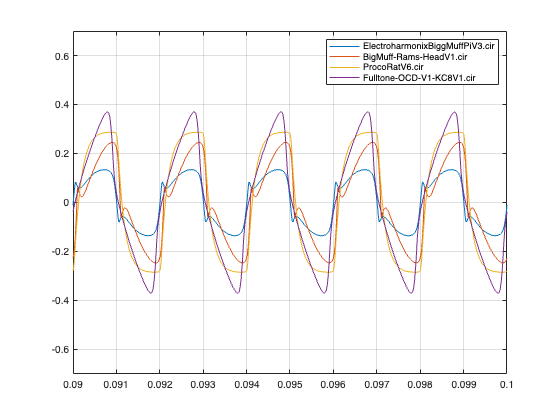

x4 = out4(:,2);
y4 = out4(:,3);

figure,plot(x1,y1,x2,y2,x3,y3,x4,y4);
xlim([0.09 0.1]);
ylim([-0.7 0.7]);
grid on;
legend(pdls);